# Robustness of Cutoff Distance for Stricter Metrics

## 1. Check robustness of disordered clusters to different cut-offs, because this will potentially effect later stuff.

In order to do this, we must first run testAromatic over a series of different values.  For this, see Analysis_and_run_code/coarsegraining/cutoffs

Running cutoffrepeat.bash will get us a series of average cluster sizes depending on cutoff for a number of different final systems.  Then we must look at all of these systems, to test for robustness of the 0.5 cutoff.

addpath('/home/rachael/Analysis_and_run_code/','/home/rachael/Analysis_and_run_code/coarsegraining/cutoffs');
cutoffs = 0.1:0.1:1.5;
dir1 = '/home/rachael/cluster/data/mansbac2/coarsegraining/MD/DFAG/'

dir1 = /home/rachael/cluster/data/mansbac2/coarsegraining/MD/DFAG/

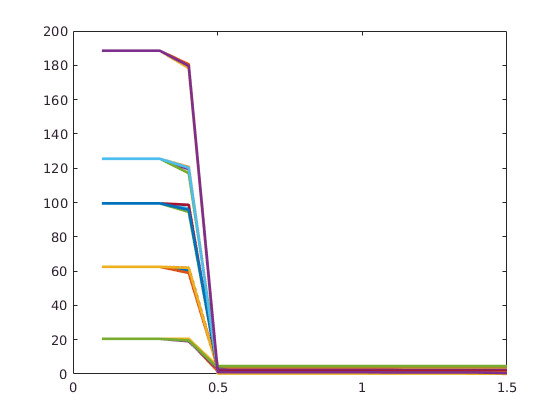

dir2 = '/4_md/aromadata';
dirs = {'42mols_run1' '42mols_run2' '42mols_run3' '42mols_run4' '42mols_run5' '126mols_run1' '126mols_run2' '126mols_run3' '126mols_run4' '126mols_run5' '200mols_run1' '200mols_run2' '200mols_run3' '200mols_run4' '200mols_run5' '252mols_run1' '252mols_run2' '252mols_run3' '252mols_run4' '252mols_run5' '378mols_run1' '378mols_run2' '378mols_run3' '378mols_run4' '378mols_run5'};
ms = zeros(length(cutoffs),length(dirs));
for d = 1:length(dirs)
   dir = [dir1 dirs{d} dir2];
   m = diffcutoffs(dir,cutoffs,'cut_','.dat');
   ms(:,d) = m;
end
figure()
plot(cutoffs,ms,'linewidth',2)

We see from the plot that this cutoff is robust for distances between 0.6 and 0.8 angstroms; therefore, perhaps we should rerun with a cutoff of 0.7 for everything?  

## 2. Import Data of Last Frame For Different Cut-off Distances

Now that we've checked that the disordered cluster cutoff is robust, we must find out how robust the other two cluster cutoffs are.  We run all of the data at a cutoff of 0.5 from a cutoff of 0.5 for disordered metric, as per previous.

## Optical Clusters

cutoffs = 0.6:0.1:0.8

cutoffs =     0.6000    0.7000    0.8000


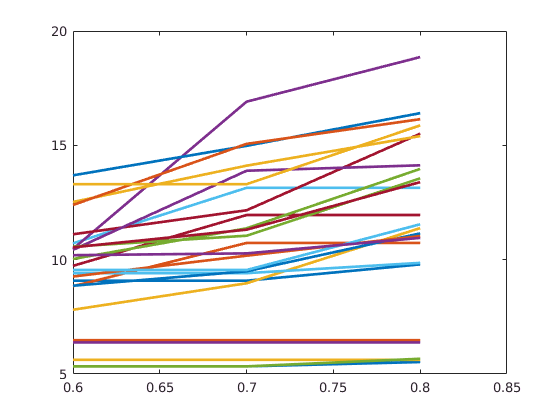

dists1 = {};
dists2 = {};
pdiffs1 = zeros(length(cutoffs),1);
ms = zeros(length(cutoffs),length(dirs));
for d = 1:length(dirs)
   dir = [dir1 dirs{d} dir2];
   m = diffcutoffs(dir,cutoffs,'cut_met1_','.dat');
   ms(:,d) = m;
   pdiff = (m(end)-m(1))/(m(end));
   pdiffs1(d) = pdiff;
end
figure()
plot(cutoffs,ms,'linewidth',2)

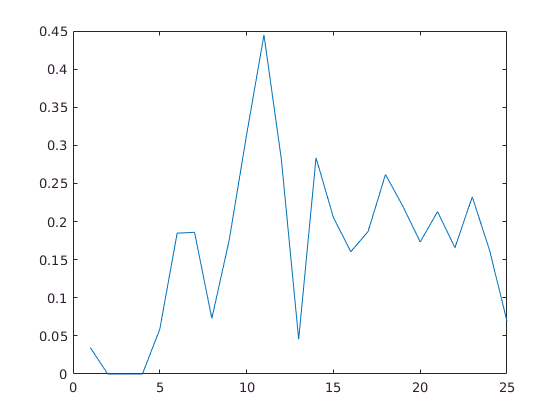

figure()
plot(pdiffs1)

## Aligned Clusters

cutoffs = 0.6:0.1:0.8;
dists1 = {};
dists2 = {};
pdiffs2 = zeros(length(cutoffs),1);
ms2 = zeros(length(cutoffs),length(dirs));
for d = 1:length(dirs)
   dir = [dir1 dirs{d} dir2];
   m2 = diffcutoffs(dir,cutoffs,'cut_met2_','.dat');
   ms2(:,d) = m2;
   pdiff = (m2(end)-m2(1))/(m2(end));
   pdiffs2(d) = pdiff;
end
figure()
plot(cutoffs,ms,'linewidth',2)

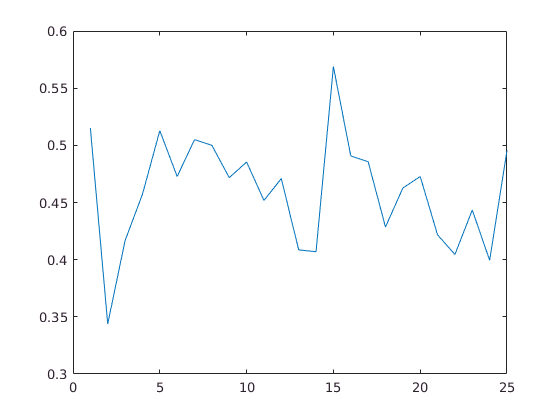

figure()
plot(pdiffs2)

## 4. Histogram Mass Sizes and Plot

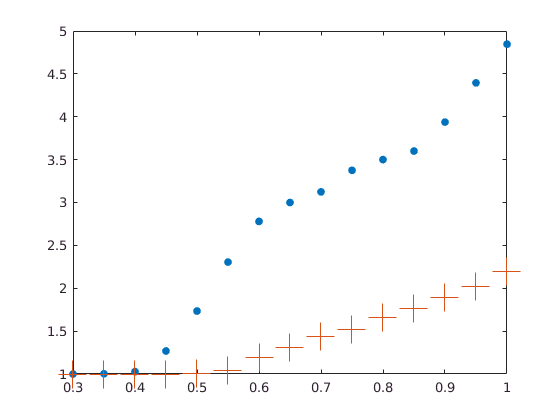

ans = 5.4945

ans = 1.7110

figure();

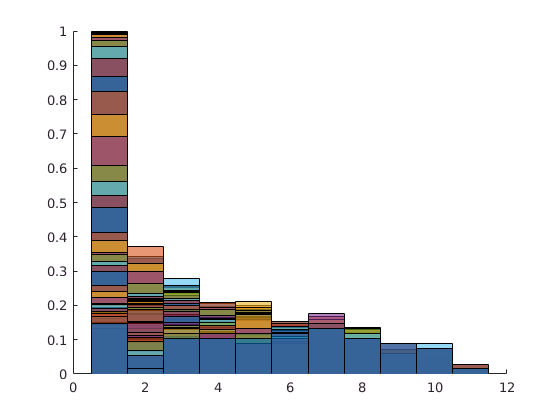

hold on;
for i = 1:length(meanmass1)
   histogram(dists1{i},'normalization','probability');
end
figure();
hold on;
for i = 1:length(meanmass2)

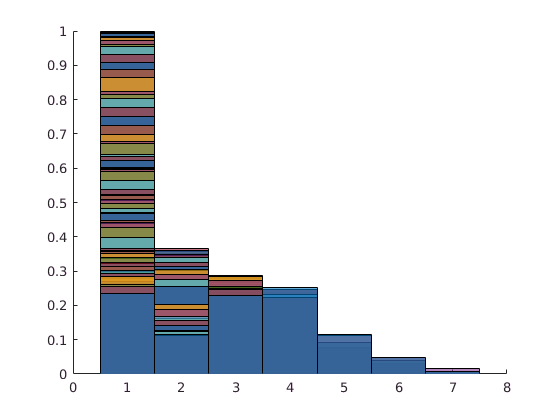

   histogram(dists2{i},'normalization','probability') 
end